## Complete program of moving the tooltip round a circle $ABCD$

Please run part a) and b) of the main file before running this.

The full explanation of the code is in the main file, including internal output results.

Parameters to be specified:

r_pts = 0.06; % radius of the circle (m)
time_total = 10; % total time (s)

% for any points, only need to specify x y coordinates
pts_xy = [r_pts      0 -r_pts     0
              0 -r_pts      0 r_pts];
pt_names= 'ABCD';

% inverse kinematics
t_pts = zeros(3, 4); % joint variables
way_pts = zeros(3, 4); % way points, with z coordinate calculated here
for i = 1: 4
    [t_pts(:, i), way_pts(:, i)] = inv_kin(pts_xy(:, i));
end

% way points normalization
t_pts_curr = t_pts; % starting points of each segment in joint space
t_pts_nxt = [t_pts(:, 2: end), t_pts(:, 1)]; % ending points of each segment
for i = 1: 4
    % restrict the rotating distance to less than pi
    idx = find(abs(t_pts_curr(:, i) - t_pts_nxt(:, i)) > pi);
    for j = 1: length(idx)
        % if distance more than pi, add the smaller one by 2*pi to avoid
        if t_pts_curr(idx(j), i) < t_pts_nxt(idx(j), i)
            t_pts_curr(idx(j), i) = t_pts_curr(idx(j), i) + 2 * pi;
        else
            t_pts_nxt(idx(j), i) = t_pts_nxt(idx(j), i) + 2 * pi;
        end
    end
end

% specify velocity at way points using average method
avg_seg_v = (t_pts_nxt - t_pts_curr) / (time_total / 4);
v_des = (avg_seg_v(:, 1: 3) + avg_seg_v(:, 2: 4)) / 2;
v_pts_bgn = [zeros(3, 1) v_des]; % starting velocity
v_pts_end = [v_des zeros(3, 1)]; % ending velocity
a_pts_bgn = zeros(3, 4);
a_pts_end = zeros(3, 4);

% quintic polynomial parameter calculation
a = cell(1, 4); % quintic polynomial parameters for all 4 segs
for i = 1: 4
    a{i} = [t_pts_curr(:, i), v_pts_bgn(:, i), a_pts_bgn(:, i) / 2,...
            (20*t_pts_nxt(:, i)-20*t_pts_curr(:, i)-(8*v_pts_end(:, i)+12*v_pts_bgn(:, i))*time_total/4-(3*a_pts_bgn(:, i)-a_pts_end(:, i))*(time_total/4)^2)/(2*(time_total/4)^3),...
            (30*t_pts_curr(:, i)-30*t_pts_nxt(:, i)+(14*v_pts_end(:, i)+16*v_pts_bgn(:, i))*time_total/4+(3*a_pts_bgn(:, i)-2*a_pts_end(:, i))*(time_total/4)^2)/(2*(time_total/4)^4),...
            (12*t_pts_nxt(:, i)-12*t_pts_curr(:, i)-(6*v_pts_end(:, i)+6*v_pts_bgn(:, i))*time_total/4-(a_pts_bgn(:, i)-a_pts_end(:, i))*(time_total/4)^2)/(2*(time_total/4)^5)];
end

% joint angles computation using polynomial
time_seg = 0: time_total / (4 * 1e3): time_total / 4; % 1000 steps for each segment
% the starting time of each segment needs to be zero under polynomial computation
joint_angles_segs = cell(1, 4); % joint angle of all joints in each segment
joint_rates_segs = cell(1, 4); % joint rates
for i = 1: 4
    if i ~= 4 % not last seg
        time_seg_i = time_seg(1: 1000); % discard duplicated ending point
    else
        time_seg_i = time_seg;
    end
    joint_angles_segs{i} = zeros(3, length(time_seg_i));
    joint_rates_segs{i} = zeros(3, length(time_seg_i));
    for j = 1: 3
        [joint_angles_segs{i}(j, :), joint_rates_segs{i}(j, :)] = ...
            poly_5th_and_4th(time_seg_i, a{i}(j, :)); % compute each segment using polynomial
    end
end

Time-consuming computation starts here:

% compute endpoint position with kinematics
% this segment is time-consuming. Don't run together with other segs
pos_A_segs = cell(1, 4); % position of point A in each seg
for i = 1: 4
    pos_A_segs{i} = zeros(3, length(joint_angles_segs{i}));
    for j = 1: length(joint_angles_segs{i})
        % position from inverse kinematics
        pos_A_segs{i}(:, j) = vpa( ...
            subs(T_A{4}(1: 3, 4), t, joint_angles_segs{i}(:, j)));
    end
end

% calculate reaction force on tooltip
% this segment is also time-consuming
N_x3_0 = 0.04 * T{4}(1: 3, 1);
f_N_0 = 0.4 * [0 0 -1]';
joint_angles = cell2mat(joint_angles_segs); % re-generation of angles in radius
F_0_part = zeros(6, 4001);
for i = 1: 4001
    F_0_part(:, i) = subs([f_N_0; N_x3_0], t, joint_angles(:, i));
end
% calculate instantaneous f_t_0
pos_A = cell2mat(pos_A_segs);
pos_A_xy = pos_A(1: 2, :);
f_t_0 = [-pos_A_xy(2, :); pos_A_xy(1, :)] ./ vecnorm(pos_A_xy) * 0.4; % direction is [-y, x]; value is 4
f_t_0 = [f_t_0; zeros(1, 4001)];
% full F_0
F_0 = F_0_part;
F_0(1: 3, :) = F_0(1: 3, :) + f_t_0;

% compute equivalent joint torques
% a more time-consuming segment
tau_0 = zeros(3, 4001);
for i = 1: 4001
    % substitude F and theta into torque formula
    tau_0(:, i) = subs(subs(tau_0_1, F, F_0(:, i)), t, joint_angles(:, i));
end

Plotting:

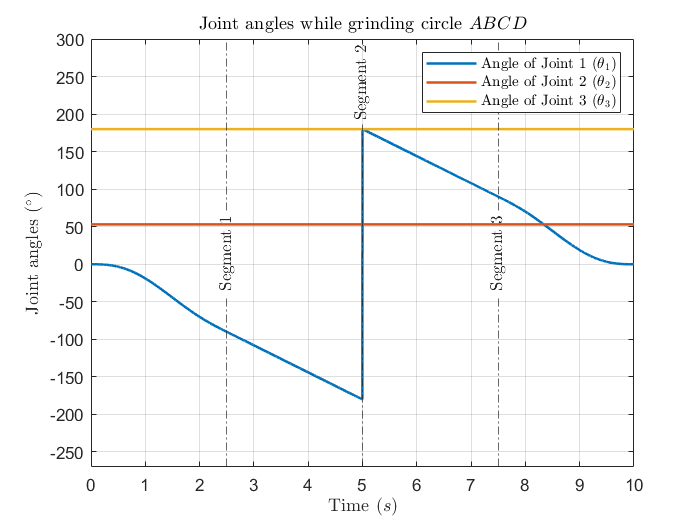

time = 0: time_total / 4e3: time_total; % 4001 steps for total time

% consecutive type for plotting
joint_angles = cell2mat(joint_angles_segs);
joint_angles = rad2deg(wrapToPi(joint_angles)); % conversion
joint_rates = cell2mat(joint_rates_segs);
joint_rates = rad2deg(joint_rates); % conversion

% plot joint angles versus time
figure
plot(time, joint_angles, 'LineWidth', 1.5)
axis([0, 10, -270, 300]); grid on
title('Joint angles while grinding circle $ABCD$', 'interpreter', 'latex')
xlabel('Time ($s$)', 'interpreter', 'latex')
ylabel('Joint angles ($^{\circ}$)', 'interpreter', 'latex')
legend('Angle of Joint 1 ($\theta_1$)', 'Angle of Joint 2 ($\theta_2$)',...
       'Angle of Joint 3 ($\theta_3$)', 'interpreter', 'latex')
for i = 1: 3
    xl = xline(time_total * i / 4, '-.', sprintf('Segment %d', i), ...
               'HandleVisibility','off', 'interpreter', 'latex');
    xl.LabelHorizontalAlignment = 'center';
    if i ~= 2
        xl.LabelVerticalAlignment = 'middle';
    end
end

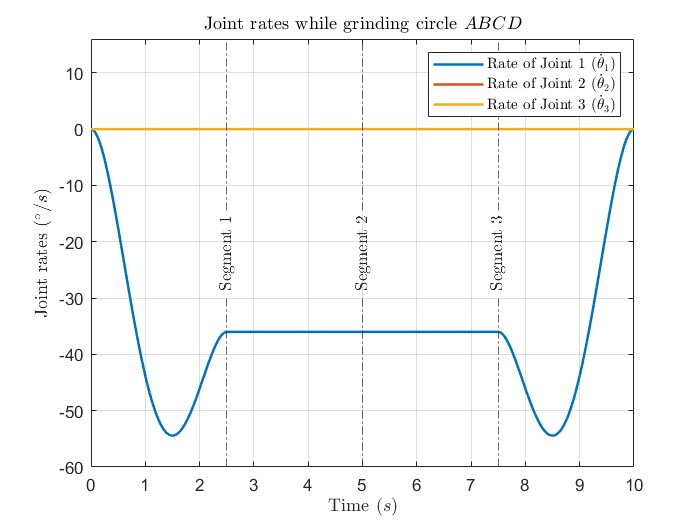


% plot joint rates versus time
figure
plot(time, joint_rates, 'LineWidth', 1.5)
axis([0, 10, -60, 16]); grid on
title('Joint rates while grinding circle $ABCD$', 'interpreter', 'latex')
xlabel('Time ($s$)', 'interpreter', 'latex')
ylabel('Joint rates ($^{\circ}/s$)', 'interpreter', 'latex')
legend('Rate of Joint 1 ($\dot{\theta}_1$)', 'Rate of Joint 2 ($\dot{\theta}_2$)',...
       'Rate of Joint 3 ($\dot{\theta}_3$)', 'interpreter', 'latex')
for i = 1: 3
    xl = xline(time_total * i / 4, '-.', sprintf('Segment %d', i), ...
               'HandleVisibility','off', 'interpreter', 'latex');
    xl.LabelHorizontalAlignment = 'center';
    xl.LabelVerticalAlignment = 'middle';
end

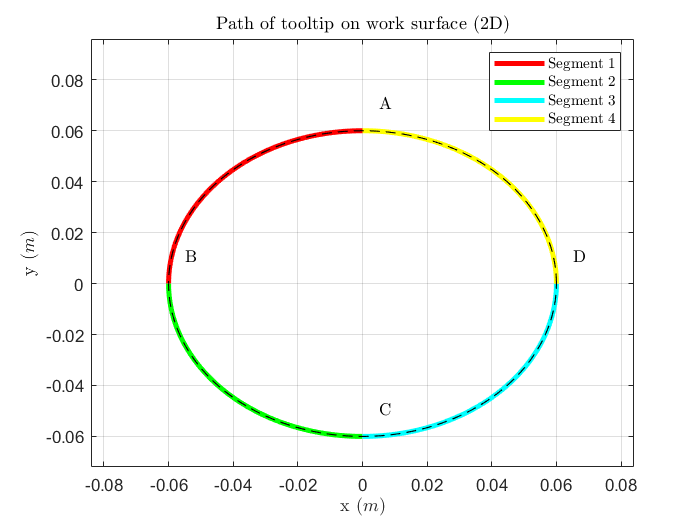


% plot endpoint position in 2D space using only x y coordinates
figure
color = 'rgcy';
for i = 1: 4
    plot(pos_A_segs{i}(2, :), pos_A_segs{i}(1, :), ... % reverse x and y
         sprintf('%s', color(i)), 'LineWidth', 3)
    hold on
end
axis([-r_pts*1.4, r_pts*1.4, -r_pts*1.2, r_pts*1.6]); grid on
title('Path of tooltip on work surface (2D)', 'interpreter', 'latex')
xlabel('x ($m$)', 'interpreter', 'latex')
ylabel('y ($m$)', 'interpreter', 'latex')
legend('Segment 1', 'Segment 2', 'Segment 3', 'Segment 4', 'interpreter', 'latex')
% reference circle
viscircles([0, 0], r_pts, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 0.7, ...
           'EnhanceVisibility', false);
% points ABCD
for i = 1: 4
    text(pts_xy(2, i)+5e-3, pts_xy(1, i)+0.01, ... % also change coordinate
         sprintf('%s', pt_names(i)), 'interpreter', 'latex')
end

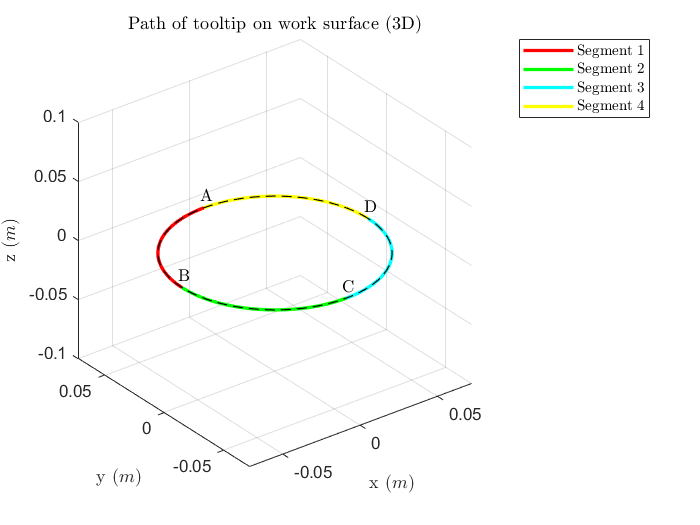


% plot endpoint position in 3D space using x, y and z coordinates
figure
color = 'rgcy';
for i = 1: 4
    plot3(pos_A_segs{i}(2, :), pos_A_segs{i}(1, :), ...
          way_pts(3, i) - pos_A_segs{i}(3, :), ... % reverse x y and subtract z
          sprintf('%s', color(i)), 'LineWidth', 2)
    hold on
end
axis([-r_pts*1.2, r_pts*1.2, -r_pts*1.2, r_pts*1.2, -0.1, 0.1]); grid on
title('Path of tooltip on work surface (3D)', 'interpreter', 'latex')
xlabel('x ($m$)', 'interpreter', 'latex')
ylabel('y ($m$)', 'interpreter', 'latex')
zlabel('z ($m$)', 'interpreter', 'latex')
legend('Segment 1', 'Segment 2', 'Segment 3', 'Segment 4', 'interpreter', 'latex')
% reference circle
viscircles([0, 0], r_pts, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 0.7, ...
           'EnhanceVisibility', false);
% points ABCD
for i = 1: 4
    text(way_pts(2, i)+5e-3, way_pts(1, i)+0.01, 0, ... % change coordinate
         sprintf('%s', pt_names(i)), 'interpreter', 'latex')
end

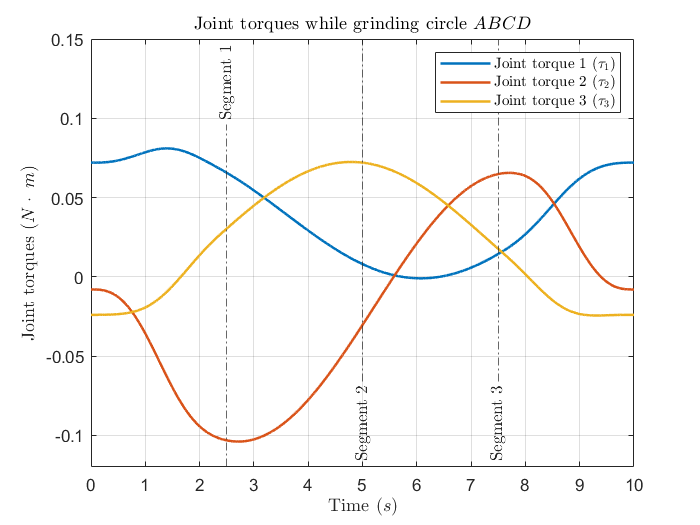


% plot joint torques with the better method
figure
plot(time, tau_0, 'LineWidth', 1.5)
axis([0, 10, -0.12, 0.15]); grid on
title('Joint torques while grinding circle $ABCD$', 'interpreter', 'latex')
xlabel('Time ($s$)', 'interpreter', 'latex')
ylabel('Joint torques ($N\cdot\;m$)', 'interpreter', 'latex')
legend('Joint torque 1 ($\tau_1$)', 'Joint torque 2 ($\tau_2$)', ...
       'Joint torque 3 ($\tau_3$)', 'interpreter', 'latex')
for i = 1: 3
    xl = xline(time_total * i / 4, '-.', sprintf('Segment %d', i), ...
               'HandleVisibility','off', 'interpreter', 'latex');
    xl.LabelHorizontalAlignment = 'center';
    if i ~= 1
        xl.LabelVerticalAlignment = 'bottom';
    end
end

function [t, p] = inv_kin(pxy)
% exported inverse kinematics function
% input:  x and y coordinates of endpoint position
% output: computed joint variables and the 3x1 endpoint position
    p = [pxy; sqrt(0.15^2 + 0.1^2 - sum(pxy.^2)) + 2/5]; % compute z coordinate in workspace
    v_o1_a = p - [0, 0, 2/5]';
    v1 = cross(v_o1_a, [1, 0, 0]'); % vectors a and b
    if v1 == [0, 0, 0]'
        v1 = cross(v_o1_a, [0, 1, 0]');
    end
    v1 = v1 / norm(v1);
    v2 = cross(v_o1_a, v1);
    v2 = v2 / norm(v2);
    pc = p - 4 / 13 * v_o1_a; % centre
    r = 0.15 * 0.1 / norm([0.15, 0.1]); % radius
    if v2(3) == 0 % obtain the minimized PBz
        alpha = pi / 2 * sign(v1(3));
        phi = 1.5 * pi - alpha;
    else
        alpha = atan(v1(3) / v2(3));
        if v2(3) > 0
            phi = 1.5 * pi - alpha;
        else
            phi = pi / 2 - alpha;
        end
    end
    pB = pc + r * cos(phi) * v1 + r * sin(phi) * v2;
    % solve inverse kinematics
    t_2 = acos((20 * pB(3) - 8) / 3); % keep +ve soln
    if sin(t_2) == 0
        t_1 = 0;
    else
        t_1 = atan2(20 * pB(2) / (3 * sin(t_2)), 20 * pB(1) / (3 * sin(t_2)));
    end
    t_3 = atan2(10 * (p(2) * cos(t_1) - p(1) * sin(t_1)), ...
                4 * sin(t_2) + 10 * (p(1) * cos(t_1) .* cos(t_2) + ...
                                     p(2) * sin(t_1) .* cos(t_2) - ...
                                     p(3) * sin(t_2)));
    t = [t_1 t_2 t_3]';
end

function [posi, velo] = poly_5th_and_4th(t, paras)
% function that returns an array of polynomial and its derivative
% according to parameters
    posi = paras(1) + paras(2) * t + paras(3) * t .^ 2 +...
           paras(4) * t .^ 3 + paras(5) * t .^ 4 + paras(6) * t .^ 5;
    velo = paras(2) + 2 * paras(3) * t + 3 * paras(4) * t .^ 2 +...
           4 * paras(5) * t .^ 3 + 5 * paras(6) * t .^ 4;
end